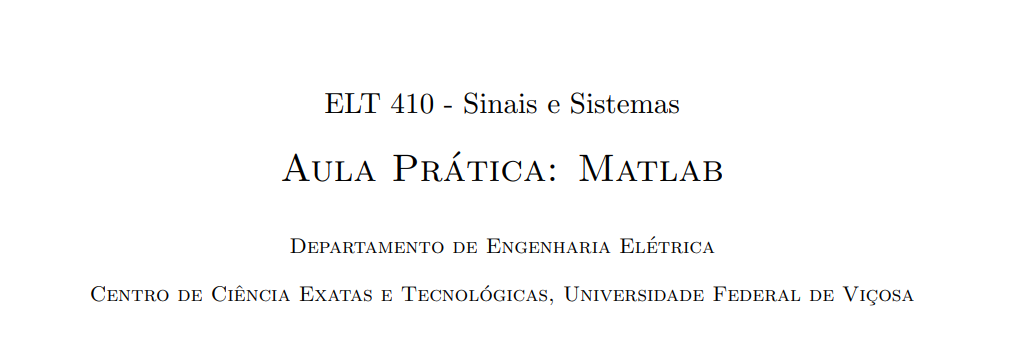

## Aula Pática 1 

05/05/2022

**Aluno:** Déric A. F. de Sales - 96718

clear all; close all; clc;

### **Parte 1 - Operações**

#### Definindo matrizes

A = randi(10,5,5)

A =      9     4     3    10     5
     6     5     2     5     2
     7     3     3     2     3
     6     9     5    10     5
     3     2     4    10     6


B = randn(5)

B =    -0.2612   -0.7411   -0.4570   -0.0290    0.0983
    0.4434   -0.5078    1.2424    0.1825    0.0414
    0.3919   -0.3206   -1.0667   -1.5651   -0.7342
   -1.2507    0.0125    0.9337   -0.0845   -0.0308
   -0.9480   -3.0292    0.3503    1.6039    0.2323


C = ones(5);
D = [1 2 3 4 5;
     6 7 8 9 10;
     11 12 13 14 15;
     16 17 18 19 20;
     21 22 23 24 25];
 
E = zeros(5);

#### Realizando Operações

soma = D + C

soma =      2     3     4     5     6
     7     8     9    10    11
    12    13    14    15    16
    17    18    19    20    21
    22    23    24    25    26


subtracao = soma - C

subtracao =      1     2     3     4     5
     6     7     8     9    10
    11    12    13    14    15
    16    17    18    19    20
    21    22    23    24    25


multiplicacao = A*D

multiplicacao =    331   362   393   424   455
   180   200   220   240   260
   153   171   189   207   225
   380   415   450   485   520
   345   370   395   420   445


mult_termoatermo = A.*D

mult_termoatermo =      9     8     9    40    25
    36    35    16    45    20
    77    36    39    28    45
    96   153    90   190   100
    63    44    92   240   150


divisao = B.\C

divisao =    -3.8290   -1.3493   -2.1881  -34.4759   10.1680
    2.2552   -1.9692    0.8049    5.4809   24.1700
    2.5517   -3.1194   -0.9375   -0.6390   -1.3621
   -0.7996   80.1986    1.0710  -11.8288  -32.4531
   -1.0549   -0.3301    2.8545    0.6235    4.3039


exponenciacao = B.^2

exponenciacao =     0.0682    0.5492    0.2089    0.0008    0.0097
    0.1966    0.2579    1.5437    0.0333    0.0017
    0.1536    0.1028    1.1379    2.4494    0.5390
    1.5642    0.0002    0.8718    0.0071    0.0009
    0.8986    9.1759    0.1227    2.5726    0.0540


transposicao = D'

transposicao =      1     6    11    16    21
     2     7    12    17    22
     3     8    13    18    23
     4     9    14    19    24
     5    10    15    20    25


Plotando Gráfico de função senoidal

Temos que o gráfico de uma função senoidal é dado por:  $f(t) = A \cdot sen(\omega \cdot t + \phi)$, onde $\omega$ é a frequência angular em $\left[ \frac{radianos}{segundos} \right]$, $A$ é a amplitude, t o tempo e $\phi$ é a constante de deslocamento da função no tempo. Assim, como a função senoide tem um período de $2 \pi$ , para 3 ciclos completos, necessitamos do intervalo de 0 à $6\pi$.

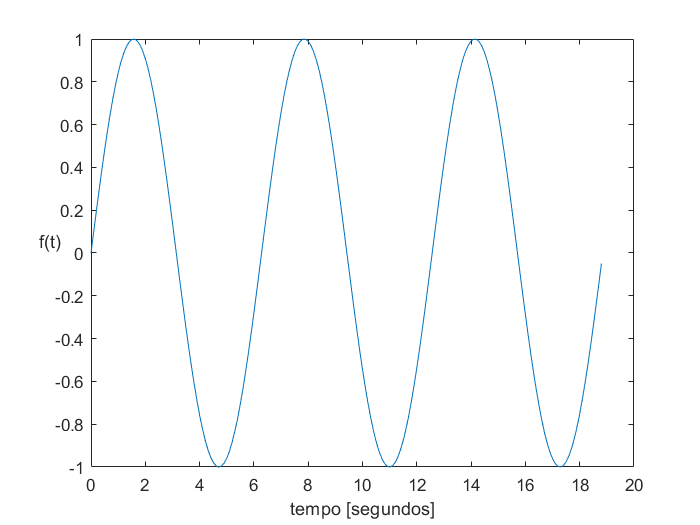

figure(1);

n_ciclos = 3;
omega = 1; % frequência angular
amp = 1; % amplitude
phi = 0; % deslocamento no tempo

t = [-0:0.1:n_ciclos*2*pi];
y = amp*sin(omega*t + phi);
graph1 = plot(t,y);

%title('Senoide com 3 ciclos completos')
xlabel('tempo [segundos]') 
ylabel('f(t)', 'rotation', 0) 

### **Parte 2 - Gráfico**

#### Gerando Gráfico do seno

figure(2);

hold on

interv = 10; % intervalo
omega = 3; % frequência angular
amp = 10; % amplitude

t = [-interv:0.1:interv]

t =   -10.0000   -9.9000   -9.8000   -9.7000   -9.6000   -9.5000   -9.4000   -9.3000   -9.2000   -9.1000   -9.0000   -8.9000   -8.8000   -8.7000   -8.6000   -8.5000   -8.4000   -8.3000   -8.2000   -8.1000   -8.0000   -7.9000   -7.8000   -7.7000   -7.6000   -7.5000   -7.4000   -7.3000   -7.2000   -7.1000   -7.0000   -6.9000   -6.8000   -6.7000   -6.6000   -6.5000   -6.4000   -6.3000   -6.2000   -6.1000   -6.0000   -5.9000   -5.8000   -5.7000   -5.6000   -5.5000   -5.4000   -5.3000   -5.2000   -5.1000



y = amp*sin(omega*t)

y =     9.8803    9.8949    9.0255    7.3500    5.0179    2.2376   -0.7427   -3.6565   -6.2438   -8.2733   -9.5638   -9.9999   -9.5429   -8.2333   -6.1884   -3.5906   -0.6721    2.3065    5.0790    7.3978    9.0558    9.9049    9.8692    8.9519    7.2349    4.8717    2.0734   -0.9102   -3.8125   -6.3742   -8.3666   -9.6115   -9.9979   -9.4912   -8.1367   -6.0554   -3.4331   -0.5042    2.4697    5.2231    7.5099    9.1258    9.9266    9.8407    8.8757    7.1179    4.7242    1.9086   -1.0775   -3.9674


graph2 = plot(t,y);


#### Acrescentando ruído com distribuição normal à curva da senoide

size_t = size(t);
ruido_n = randn(1,size_t(2));
y_ruido = y + ruido_n

y_ruido =    10.3067    9.5221    8.7891    9.3737    2.7595    4.4670   -0.4051   -2.6565   -7.9079   -8.8633   -9.8418   -9.5772  -11.2131   -7.7617   -7.4012   -3.5244   -0.0197    2.6335    6.1616    8.4039    8.4049   10.1619    8.9248    7.6301    8.1598    4.8718    2.0184    0.0009   -3.2179   -6.0240   -7.1163   -8.6817   -9.7582  -10.1816   -8.7883   -4.8633   -5.0450   -0.5287    0.5209    6.2436    8.3716    9.1270    9.8558    7.3544    9.4568    4.9254    2.4049    1.9885   -2.0260   -3.5559


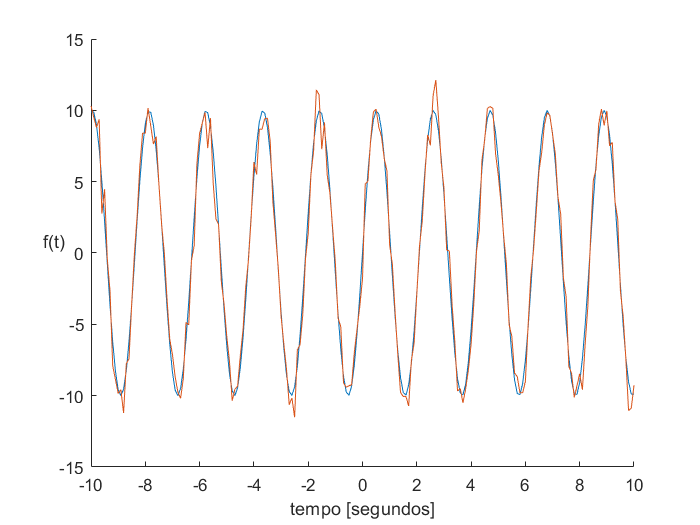

graph3 = plot(t,y_ruido);

%title('Senoide com ruido em distribuição normal')
xlabel('tempo [segundos]') 
ylabel('f(t)', 'rotation', 0) 

hold off